close all
clear
clc

## Week 5 Pod 1-Visualization

% This week's activity is designed to introduce some cool data visualization
% techiques. Feel free to copy and modify parts of this script for tour own
% work.

% Below are some exercises you can do to familiarize yourselves with these
% techniques.

## Exercieses:

% Q1. Add the One month scores from group 1 and group 2 to the figure

%       Q1a. Add array of randomly sampled numbers using the means and standard
%       deviations from 'oneMonthProperties' to each group.Use te below code
%       oneMonthProperties = struct('means', [100, 70], 'std', [10, 40]);

%       Q1b. Update 'data', 'dataLabels', and 'dataColors' for the one month scores from each
%       group

% Q2. Increase the number of participants from 10 to 100.

% Q3. Adjust Jitter width to decrease chance of points overlapping

% Q4. Add a 3rd group containing pre, post, and one month scores to the
% figure.

%       Q4a. Add a 3rd mean and standard deviation to the pre, post, and
%       one month properties

%       Q4b. Create a group3 struct

%       Q4c. Update 'data', 'dataLabels', and 'dataColors' for the 3rd
%       group

%       Q4d. Update the first 'for loop' used to connect the raw data points to
%       account for a third group

%       Q4e. Update width of boxchart, jitter size, and figure size as
%       needed

%       Q5. Upload to github

## Specify default parameters

% All figures stem from a single "graphics object" otherwise known as a
% groot. This groot serves as a template for any figure you may make so
% changing specific properties of the template (e.g. font style) will make
% changes for all subsequent figures.

% for a mostly complete list of defaults properties:
% https://undocumentedmatlab.com/articles/getting-default-hg-property-values/

% Below, I set the default properties of groot to the sizes and styles that
% fit my preference.

set(groot,'defaultAxesFontName','Ariel')
set(groot,'defaultAxesFontSize',10)
set(groot,'defaultLineLineWidth',.5)

## Simulate data for two groups

% Lets pretend we're compairing the effects of a training regimine for two
% groups of individuals.

% Each group should have 'N' participants.
N = 100;

% and each participant should have a pre assessment score, and a
% post assessment score. We can generate this data in a few steps.
% Essentially, i want to pull random numbers from a normal distribution,
% given a mean and standard deviation.

% Step 1: define the means and standard deviations for the pre and post
% assessments for each group
preProperties = struct('means', [43, 50, 47], 'std', [5, 10, 8]);
postProperties = struct('means', [80, 60, 75], 'std', [5, 25, 9]);
oneMonthProperties = struct('means', [100, 70, 90], 'std', [10, 40, 20]);

% Extra Struct Example
% subject1 = struct('age', 23, 'sex', 'M', 'handedness', 'Right', 'AssessmentDays', ["Mon", "Thur"]);

% Step 2: Create a struct for group 1 and group 2, with each group containing simulated
% data for pre and post assessment scores
group1 = struct('PreTraining', [normrnd(preProperties.means(1),preProperties.std(1),1,N)], ...
    'PostTraining', [normrnd(postProperties.means(1),postProperties.std(1),1,N)], 'oneMonth', [normrnd(oneMonthProperties.means(1),oneMonthProperties.std(1),1,N)]);

group2 = struct('PreTraining', [normrnd(preProperties.means(2),preProperties.std(2),1,N)], ...
    'PostTraining', [normrnd(postProperties.means(2),postProperties.std(2),1,N)], 'oneMonth', [normrnd(oneMonthProperties.means(2),oneMonthProperties.std(2),1,N)]);

group3 = struct('PreTraining', [normrnd(preProperties.means(3),preProperties.std(3),1,N)], ...
    'PostTraining', [normrnd(postProperties.means(3),postProperties.std(3),1,N)], 'oneMonth', [normrnd(oneMonthProperties.means(3),oneMonthProperties.std(3),1,N)]);

## Create initial figure

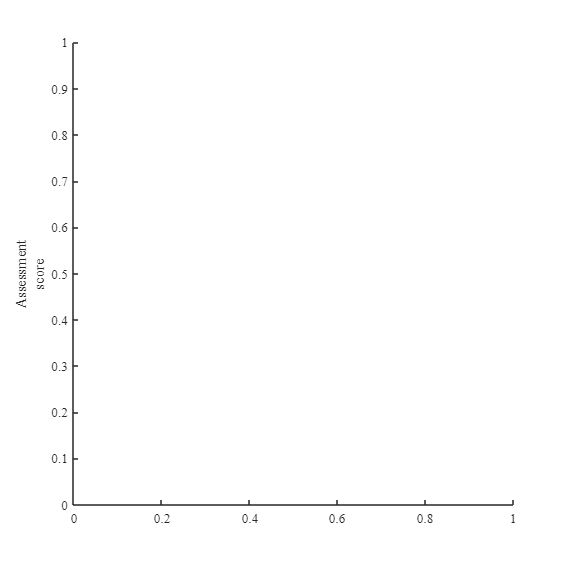

f1 = figure('NumberTitle','off','Name','Effect of training Pre vs Post vs One Month');
axes = gca();
hold on

ylabel({'Assessment';'score'})

% When setting the size of your figures, you can use the keyword
% 'Position' that takes [left, bottom, width, height]. Typically matlab
% defaults these values to pixels in order to ensure figures fit on any
% screen. When making posters, presentation, or manuscripts, you usually
% want your figure to be a specifc size. Here, I change the units and set
% the positon using centimeters.
set(f1, 'Units', 'centimeters','Position', [2,2,15,15]);

## Organize/Prepare Data

data = [group1.PreTraining; ...
    group1.PostTraining; ...
    group1.oneMonth; ...
    group2.PreTraining; ...
    group2.PostTraining; ...
    group2.oneMonth; ... 
    group3.PreTraining; ...
    group3.PostTraining; ...
    group3.oneMonth]'; ...

dataLabels = ["Group1 Pre", "Group1 Post", "Group 1 One Month", "Group2 Pre", "Group2 Post", "Group2 One Month", "Group3 Pre", "Group3 Post", "Group3 One Month"];

dark_red  = "#C70808";
cyan = "#00FFFF" ;
dark_blue  = "#23537F";
light_blue  = "#0BB8FD";
light_orange  = "#FD8B0B";
dark_cyan = "#4DBEEE" ;
dark_purple = "#9933FF";
magenta = "#FF00FF";
red = "#FF0000";



dataColors = [dark_blue, light_blue, dark_red, light_orange, cyan, dark_cyan, dark_purple, magenta, red];

## Plot boxchart and raw data

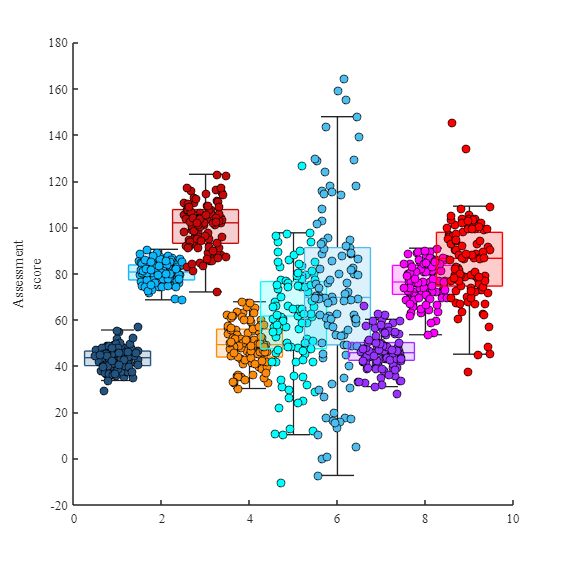

% Plotting raw data on boxcharts is an easy way to increase the transparaency of
% your science and interpretability of your figures. One common issue is
% raw data tends to overlap. To avoid this, we can slightly jitter our
% data.
jitterWidth = .50;

% We also want to connect our the pre and post data points for each group.
% Because we're going to jitter the x coordinate of our data points, we
% need to store the new x values.
storedData = struct('x', NaN(N, length(data)), 'y', NaN(N, length(data)));

% for loop to index between groups. (may need to be fixed)
for i_idx = 1:9 % 1:Total number of datasets 
    
    yData = data(:,i_idx);
    xData = ones(1,length(yData))*i_idx;
    
    % alter the xData with the specified jitter
    xData_withJitter = (i_idx - jitterWidth) + 2*(jitterWidth)*rand(1,length(yData));
    
    storedData.x(:,i_idx) = xData_withJitter;
    storedData.y(:,i_idx)  = yData;
    
    % plot the box chart
    boxchart(axes,xData, yData, 'boxfacecolor', dataColors(i_idx), 'markerstyle', 'none', 'boxwidth', 1.5) ;
    
    % plot the raw data as a scatter plot
    scatter(axes, xData_withJitter,yData, MarkerFaceColor=dataColors(i_idx), MarkerEdgeColor='black');
    
end

## Connect raw data points

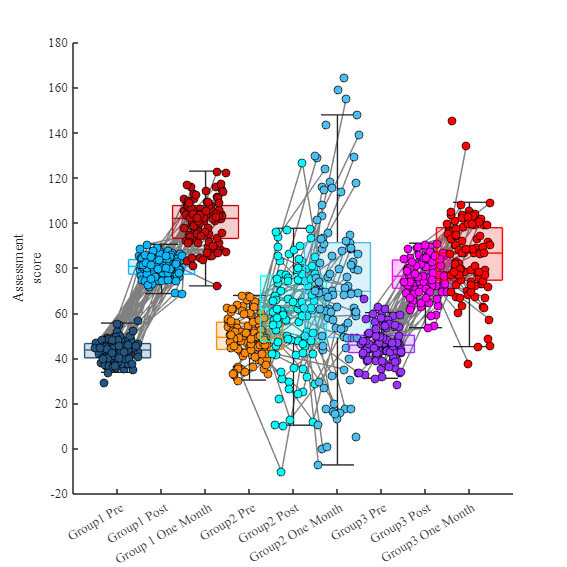

% specify the color used for the lines
grey = '#808080';

% the first for loop indexes between groups (may need to be fixed)
for k_idx = [1 4 7] % [Index of group1_pre, Index of group2_pre]
    
    % the second for loop indexes each data point (may need to be fixed)
    for j_idx = 1:50 %1:N
        
        % plot line connecting a single dataset from the pre and post of
        % each group. Assigning the plot to a varaible allows us to change
        % the properties of that plot later.
        line = plot(axes, ...
             [storedData.x(j_idx, k_idx), storedData.x(j_idx, k_idx+1), storedData.x(j_idx, k_idx+2)], ... % [groupN_pre_x, groupN_post_x, groupN_one_month_x]
             [storedData.y(j_idx, k_idx), storedData.y(j_idx, k_idx+1), storedData.y(j_idx, k_idx+2)], ... % [groupN_pre_y, groupN_post_y, groupN_one_month_y]
                'Color', grey);

        
        % Change the alpha level of the line
        set(line, 'Color', [line.Color, 0.25])
        
        % optional code to move the line to the back of the figure
        uistack(line, "bottom")
    end
end

% rename the xticks
xticks(1:9); xticklabels(dataLabels);